# Cell model 1 DOF - General model

clear all; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("1DOF\");

% Data --------------------------------------------------------------
% Constants
syms epsilon1_max
% epsilon1_max = 0.05;

% Symbolic variables ------------------------------------------------
% Physical properties
syms nu Y_p epsilon_p epsilon_f EBD_p EBD_f real positive

% Geometry of the capacitor
syms x l_0 w_0 tp_0 xi xi_0 tf_0 dt_f dtf real positive
% t_f(x) armature distance at a certain xsi

% Physical quantities
syms V

syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x) sigma_2(x)
syms eps1 eps2 eps3 s1 s2 s3

eqstrain = [
eps1 == 1 / Y_p * (s1 - nu * (s2 + s3)),...
eps2 == 1 / Y_p * (s2 - nu * (s1 + s3)),...
eps3 == 1 / Y_p * (s3 - nu * (s1 + s2))
];

sol_pstrain = solve(subs(eqstrain, {eps2, s3}, {0, 0}), {s1, s2, eps3})

sol_pstrain = struct with fields:
      s1: -(Y_p*eps1)/(nu^2 - 1)
      s2: -(Y_p*eps1*nu)/(nu^2 - 1)
    eps3: (eps1*nu)/(nu - 1)


sol_pstress = solve(subs(eqstrain, {s2, s3}, {0, 0}), {s1, eps2, eps3})

sol_pstress = struct with fields:
      s1: Y_p*eps1
    eps2: -eps1*nu
    eps3: -eps1*nu


## Geometry

% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f;

cell_1dof = struct()

cell_1dof = struct with no fields.


cell_1dof = compute_geometry1(t_f, cell_1dof, "GENERAL")

cell_1dof = struct with fields:
      w: w(x)
    t_p: t_p(x)
      l: l_0*(epsilon_1(x) + 1)
      A: l_0*w(x)*(epsilon_1(x) + 1)
     dA: w(x)*(epsilon_1(x) + 1)
    dCp: (epsilon_p*w(x)*(epsilon_1(x) + 1))/t_p(x)
    dCf: (epsilon_f*w(x)*(epsilon_1(x) + 1))/(tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)
     dC: 1/((tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)/(epsilon_f*w(x)*(epsilon_1(x) + 1)) + (2*t_p(x))/(epsilon_p*w(x)*(epsilon_1(x) + 1)))
      C: (epsilon_f*l_0*log(- 2*epsilon_f*l_0*t_p(x) - epsilon_p*l_0*tf_0)*w(x)*(epsilon_1(x) + 1))/(tf_0 - x) - (epsilon_f*l_0*log(epsilon_p*l_0*(tf_0 - x) - epsilon_p*l_0*tf_0 - 2*epsilon_f*l_0*t_p(x))*w(x)*(epsilon_1(x) + 1))/(tf_0 - x)
    Vol: x*xi_0*w(x) - (w(x)*(l_0^2*(epsilon_1(x) + 1)^2 - x^2/4)^(1/2)*(tf_0 - x))/2 + 2*l_0*t_p(x)*w(x)*(epsilon_1(x) + 1)


l = cell_1dof.l;
t_p = cell_1dof.t_p;
w = cell_1dof.w;
A = l * w;
cell_1dof.Cplane = (2 / (A * epsilon_p / t_p) + 1 / (A * epsilon_f / t_f))^(-1);
cell_1dof.Cplane = simplify(subs(cell_1dof.Cplane, {x, w, t_p, epsilon_1}, {tf_0, w_0, tp_0, 0}))

cell_1dof = struct with fields:
         w: w(x)
       t_p: t_p(x)
         l: l_0*(epsilon_1(x) + 1)
         A: l_0*w(x)*(epsilon_1(x) + 1)
        dA: w(x)*(epsilon_1(x) + 1)
       dCp: (epsilon_p*w(x)*(epsilon_1(x) + 1))/t_p(x)
       dCf: (epsilon_f*w(x)*(epsilon_1(x) + 1))/(tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)
        dC: 1/((tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)/(epsilon_f*w(x)*(epsilon_1(x) + 1)) + (2*t_p(x))/(epsilon_p*w(x)*(epsilon_1(x) + 1)))
         C: (epsilon_f*l_0*log(- 2*epsilon_f*l_0*t_p(x) - epsilon_p*l_0*tf_0)*w(x)*(epsilon_1(x) + 1))/(tf_0 - x) - (epsilon_f*l_0*log(epsilon_p*l_0*(tf_0 - x) - epsilon_p*l_0*tf_0 - 2*epsilon_f*l_0*t_p(x))*w(x)*(epsilon_1(x) + 1))/(tf_0 - x)
       Vol: x*xi_0*w(x) - (w(x)*(l_0^2*(epsilon_1(x) + 1)^2 - x^2/4)^(1/2)*(tf_0 - x))/2 + 2*l_0*t_p(x)*w(x)*(epsilon_1(x) + 1)
    Cplane: [1×1 symfun]


cell_1dof.C = piecewise(x <= tf_0+1e-10, cell_1dof.Cplane, x > tf_0+1e-10, cell_1dof.C)

cell_1dof = struct with fields:
         w: w(x)
       t_p: t_p(x)
         l: l_0*(epsilon_1(x) + 1)
         A: l_0*w(x)*(epsilon_1(x) + 1)
        dA: w(x)*(epsilon_1(x) + 1)
       dCp: (epsilon_p*w(x)*(epsilon_1(x) + 1))/t_p(x)
       dCf: (epsilon_f*w(x)*(epsilon_1(x) + 1))/(tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)
        dC: 1/((tf_0 - ((tf_0 - x)*(l_0 - xi + xi_0))/l_0)/(epsilon_f*w(x)*(epsilon_1(x) + 1)) + (2*t_p(x))/(epsilon_p*w(x)*(epsilon_1(x) + 1)))
         C: [1×1 symfun]
       Vol: x*xi_0*w(x) - (w(x)*(l_0^2*(epsilon_1(x) + 1)^2 - x^2/4)^(1/2)*(tf_0 - x))/2 + 2*l_0*t_p(x)*w(x)*(epsilon_1(x) + 1)
    Cplane: [1×1 symfun]



% Range limit
x_min = tf_0

$$x\_min = {\mathrm{tf}}_{0}$$

cell_1dof.x_min = x_min;

x_max = (epsilon_1(x)) == epsilon1_max

$$x\_max = \epsilon_{1}\left(x\right)=\epsilon_{1,\max}$$

cell_1dof.x_max = x_max;
% Volume
cell_1dof.Vol = w * 2 * t_p * l + w * (x - tf_0) / 2 * sqrt(l^2 - (x / 2)^2);
cell_1dof.Vol_0 = w_0 * 2 * tp_0 * l_0;

## Voltage

% Voltage
makeassumptions
Vmax(x) = 2 * t_p / epsilon_p * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

$$Vmax(x) = \frac{2\,t_{p}\left(x\right)\,\min\left(\left[{\mathrm{EBD}}_{f}\,\epsilon_{f},{\mathrm{EBD}}_{p}\,\epsilon_{p}\right],\left[\right],2,\text{"omitnan"},\mathrm{symfalse}\right)}{\epsilon_{p}}$$

cell_1dof.Vmax = Vmax;

## Energy

Uel(x) = 2 * 1 / 2 * sigma_1 * epsilon_1 * w * t_p * l

$$Uel(x) = l_{0}\,\epsilon_{1}\left(x\right)\,\sigma_{1}\left(x\right)\,t_{p}\left(x\right)\,w\left(x\right)\,\left(\epsilon_{1}\left(x\right)+1\right)$$

cell_1dof.Uel = Uel;

## Force 

F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(cell_1dof.C, x))

FVmin = F(x,0)

$$FVmin = \left\{ \begin{array}{cl} l_{0}\,\epsilon_{1}\left(x\right)\,\sigma_{1}\left(x\right)\,t_{p}\left(x\right)\,w\left(x\right)\,\frac{\partial }{\partial x}\epsilon_{1}\left(x\right)+l_{0}\,\epsilon_{1}\left(x\right)\,\sigma_{1}\left(x\right)\,t_{p}\left(x\right)\,\left(\epsilon_{1}\left(x\right)+1\right)\,\frac{\partial }{\partial x}w\left(x\right)+l_{0}\,\epsilon_{1}\left(x\right)\,\sigma_{1}\left(x\right)\,w\left(x\right)\,\left(\epsilon_{1}\left(x\right)+1\right)\,\frac{\partial }{\partial x}t_{p}\left(x\right)+l_{0}\,\epsilon_{1}\left(x\right)\,t_{p}\left(x\right)\,w\left(x\right)\,\left(\epsilon_{1}\left(x\right)+1\right)\,\frac{\partial }{\partial x}\sigma_{1}\left(x\right)+l_{0}\,\sigma_{1}\left(x\right)\,t_{p}\left(x\right)\,w\left(x\right)\,\left(\epsilon_{1}\left(x\right)+1\right)\,\frac{\partial }{\partial x}\epsilon_{1}\left(x\right) & \text{ if }10000000000\,{\mathrm{tf}}_{0}+1\neq 10000000000\,x \end{array}\right.$$

FVmax = F(x,Vmax)

cell_1dof.F = F;
cell_1dof.FVmin = FVmin;
cell_1dof.FVmax = FVmax;

pstrain_1dof = compute_geometry1(t_f, cell_1dof, "PSTRAIN");
pstress_1dof = compute_geometry1(t_f, cell_1dof, "PSTRESS");
nostrain_1dof = compute_geometry1(t_f, cell_1dof, "NO_STRAIN");

l0_range = sdata1(l_0) * ((1-0.9):0.45:(1+1.8))

$$l0\_range = \left(\begin{array}{ccccccc} \frac{1}{400} & \frac{11}{800} & \frac{1}{40} & \frac{29}{800} & \frac{19}{400} & \frac{47}{800} & \frac{7}{100} \end{array}\right)$$


myfig(1,""); hold on

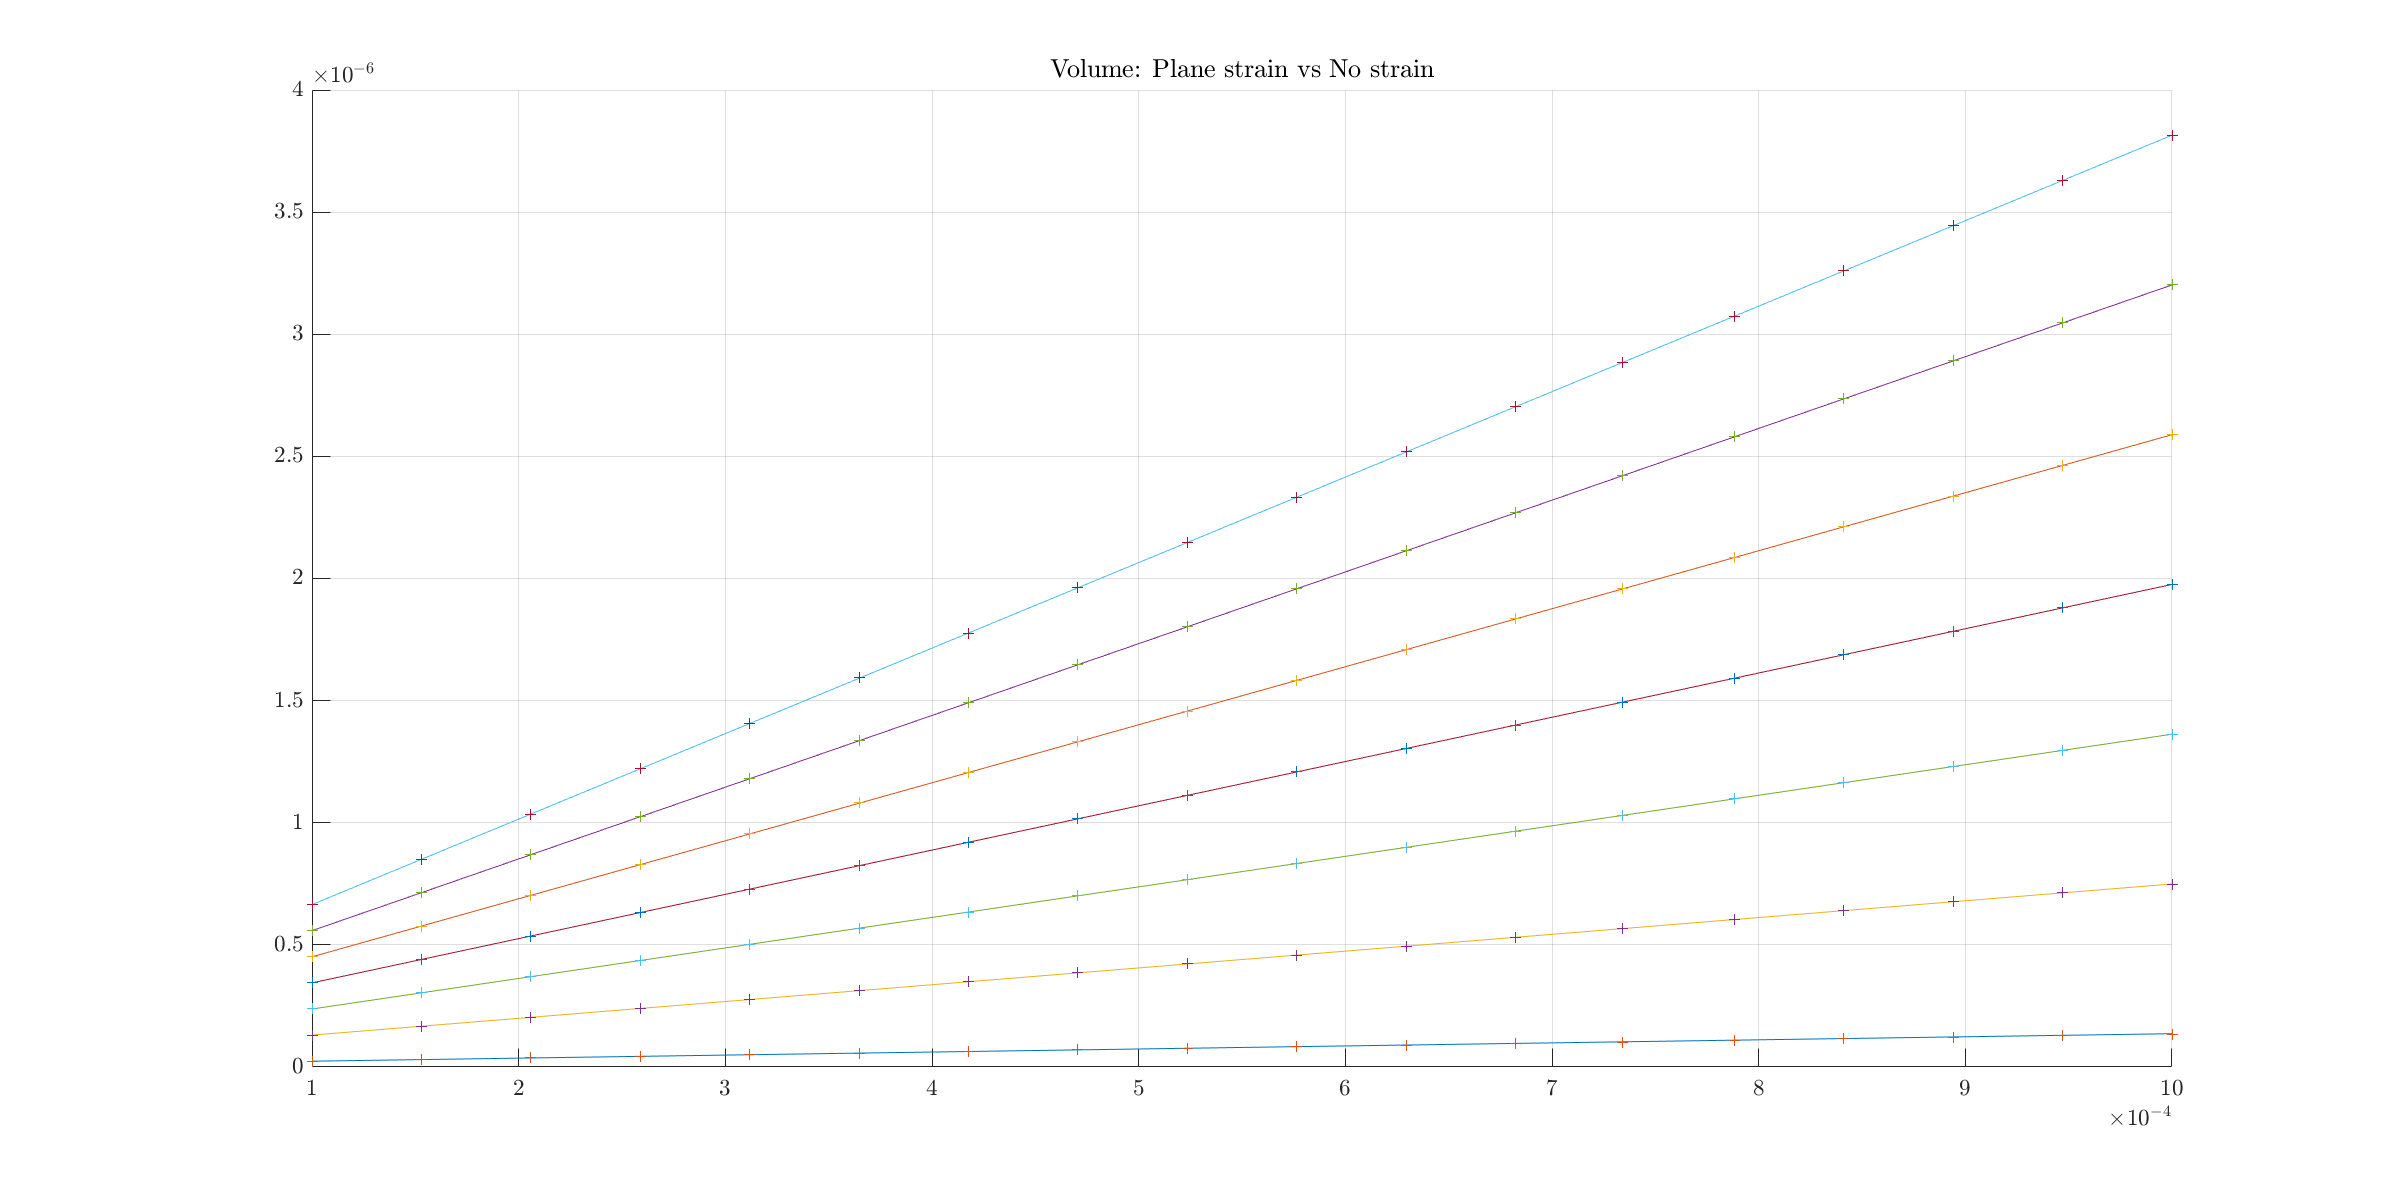

Vol_l0_pstrain = sdata1(sstrain1(pstrain_1dof.Vol, "PSTRAIN"), 'except', l_0);
Vol_l0_nostr = sdata1(sstrain1(pstrain_1dof.Vol, "NO_STRAIN"), 'except', l_0);
for i = 1:length(l0_range)
    fplot(subs(Vol_l0_pstrain, l_0, l0_range(i)), [1e-4 1e-3])
    fplot(subs(Vol_l0_nostr, l_0, l0_range(i)), [1e-4 1e-3], '+')
end
title("Volume: Plane strain vs No strain")


myfig(2,""); hold on
Vol_l0_pstress = sdata1(sstrain1(pstress_1dof.Vol, "PSTRESS"), 'except', l_0);
Vol_l0_nostr = sdata1(sstrain1(pstress_1dof.Vol, "NO_STRAIN"), 'except', l_0);
for i = 1:length(l0_range)
    fplot(subs(Vol_l0_pstress, l_0, l0_range(i)), [1e-4 1e-3])
    fplot(subs(Vol_l0_nostr, l_0, l0_range(i)), [1e-4 1e-3], '+')
end
title("Volume: Plane stress vs No strain")

cell_1dof.Vol = w_0 * 2 * tp_0 * l_0 + w_0 * (x - tf_0) / 2 * l_0 + x * xi_0 * w_0;
pstrain_1dof.Vol = cell_1dof.Vol;
pstress_1dof.Vol = cell_1dof.Vol;
nostrain_1dof.Vol = cell_1dof.Vol;


save("1DOF\cell_1dof.mat", "cell_1dof")
save("1DOF\cell_1dof_pstrain.mat", "pstrain_1dof")
save("1DOF\cell_1dof_pstress.mat", "pstress_1dof")
save("1DOF\cell_1dof_nostrain.mat", "nostrain_1dof")

